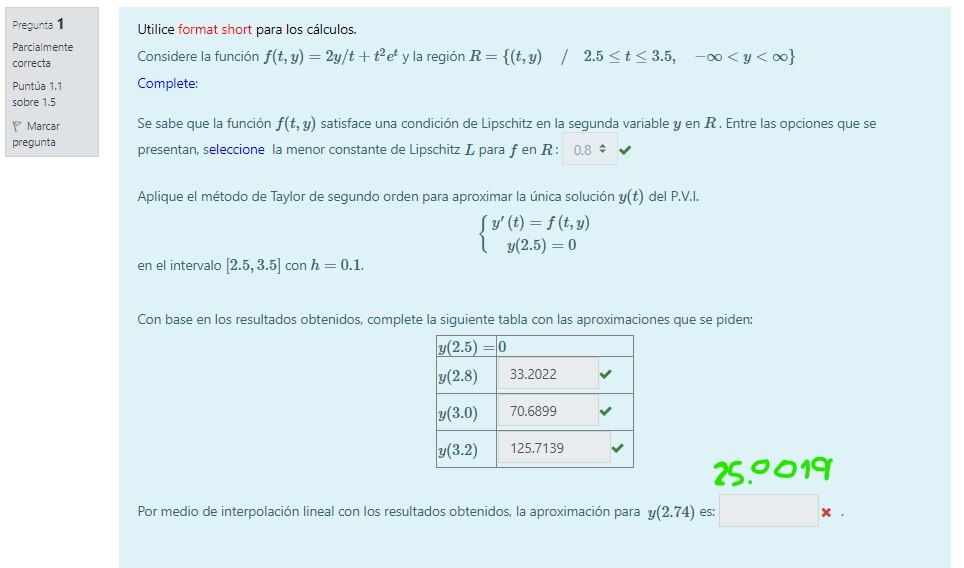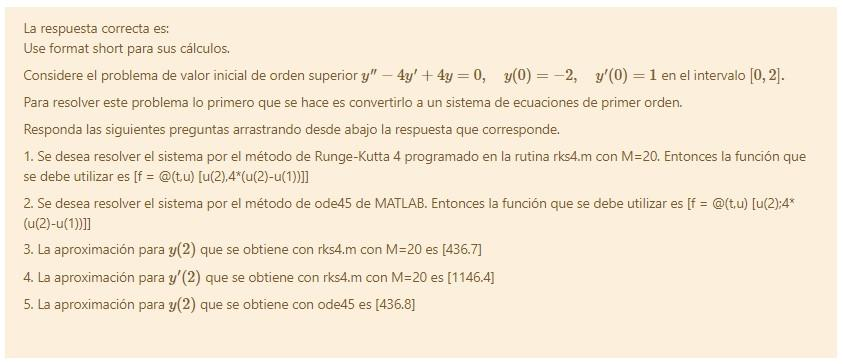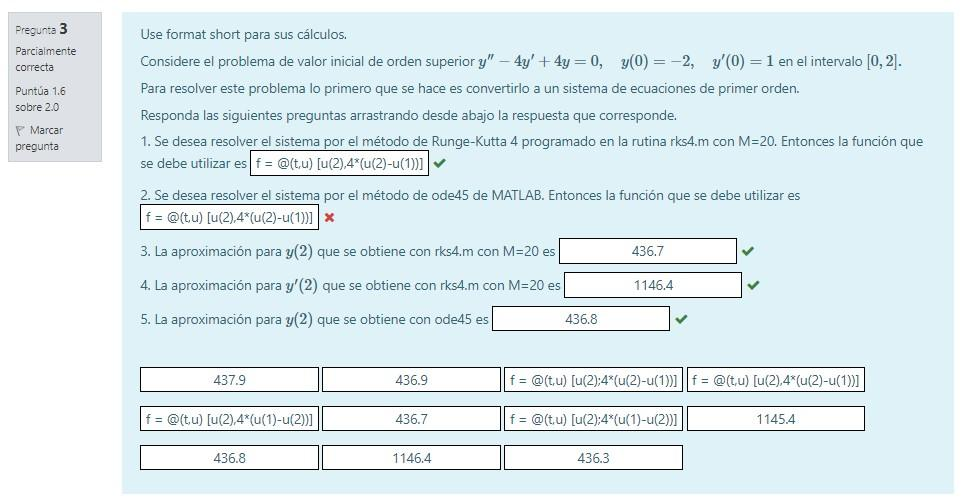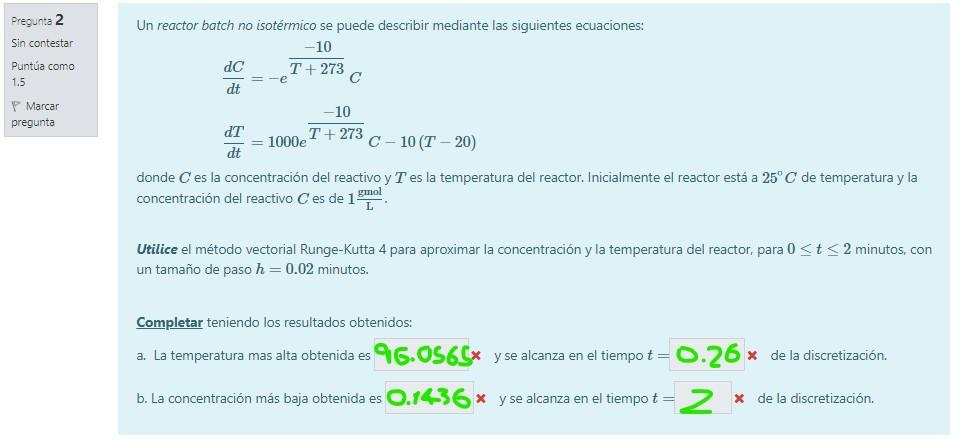

f=@(t,u) [-u(1)*exp((-10)/(u(2)-273)) , u(1)*1000*exp(-10/(u(2)-273))-10*(u(2)-20)]

f = function_handle with value:
    @(t,u)[-u(1)*exp((-10)/(u(2)-273)),u(1)*1000*exp(-10/(u(2)-273))-10*(u(2)-20)]


Za = [1 25];
a=0; b=2; M=b/0.02;
[T, Z] = rks4 (f, a, b, Za, M)

T =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


Z =     1.0000   25.0000
    0.9794   42.7947
    0.9591   57.0321
    0.9392   68.3568
    0.9196   77.2961
    0.9005   84.2820
    0.8817   89.6683
    0.8632   93.7453
    0.8451   96.7516
    0.8274   98.8831


[T',Z]

ans =          0    1.0000   25.0000
    0.0200    0.9794   42.7947
    0.0400    0.9591   57.0321
    0.0600    0.9392   68.3568
    0.0800    0.9196   77.2961
    0.1000    0.9005   84.2820
    0.1200    0.8817   89.6683
    0.1400    0.8632   93.7453
    0.1600    0.8451   96.7516
    0.1800    0.8274   98.8831


max(Z(:,2))

ans = 101.5035

min(Z(:,1))

ans = 0.1226

    HASTA AQUI EXAMENES JEAN CARLOS 1

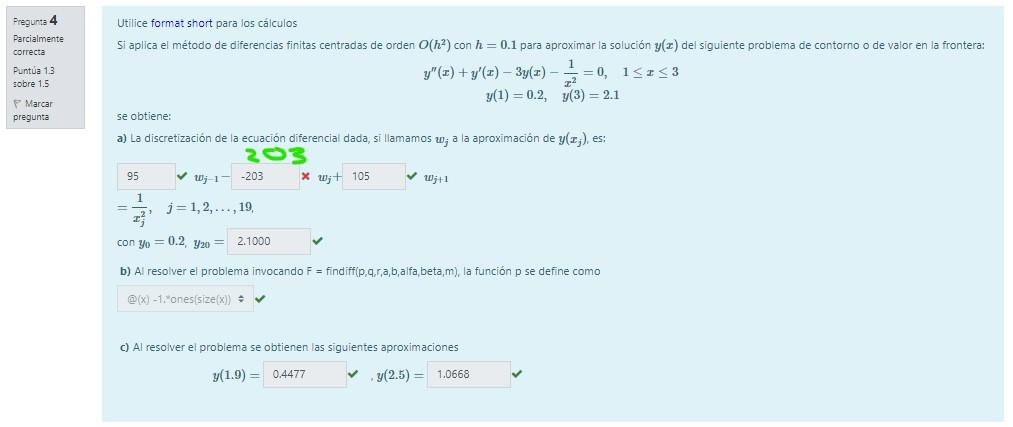

h=0.1;
(1/(h^2)+1/(2*h)*(-1))

ans = 95.0000


(2/(h^2))+3

ans = 203.0000


(1/h^2)-(1/(2*h))*(-1)

ans = 105.0000

r= @(x) 1./x.^2
p = @(x) -1.*ones(size(x));
q = @(x) 3.*ones(size(x));
h=0.1;
N=(b-a)/h
a=1
b=3
aplha= 0.2
beta =2.1
F = findiff (p, q, r, a, b, 0.2, 2.1, N)

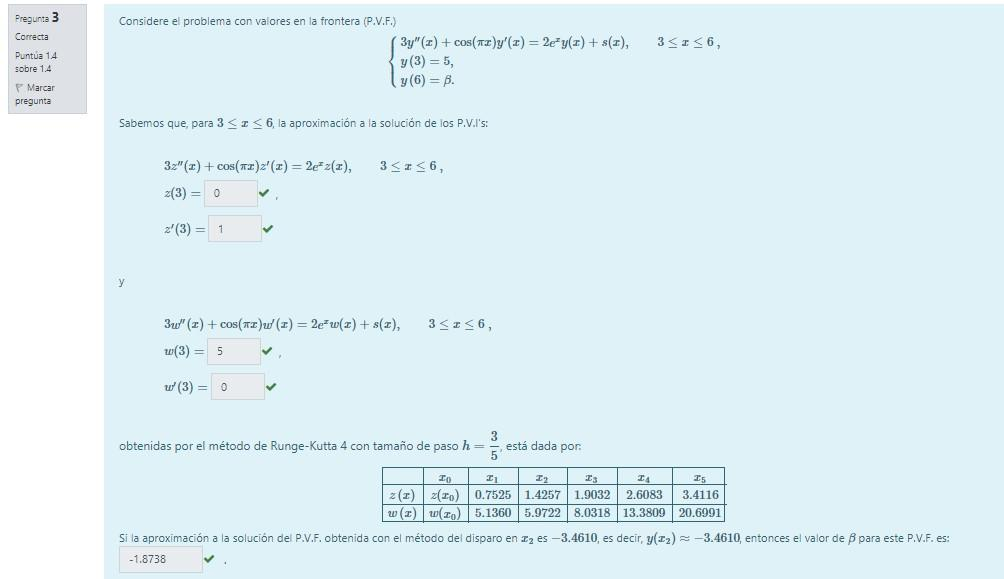

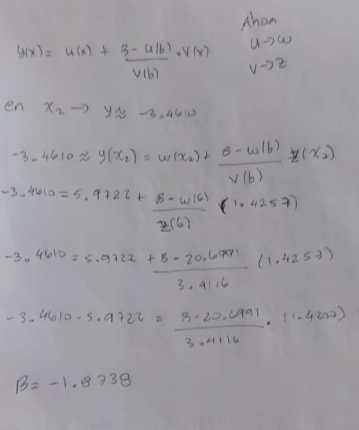

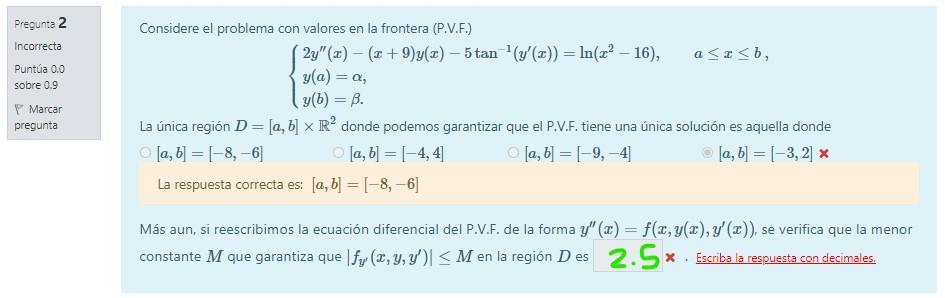

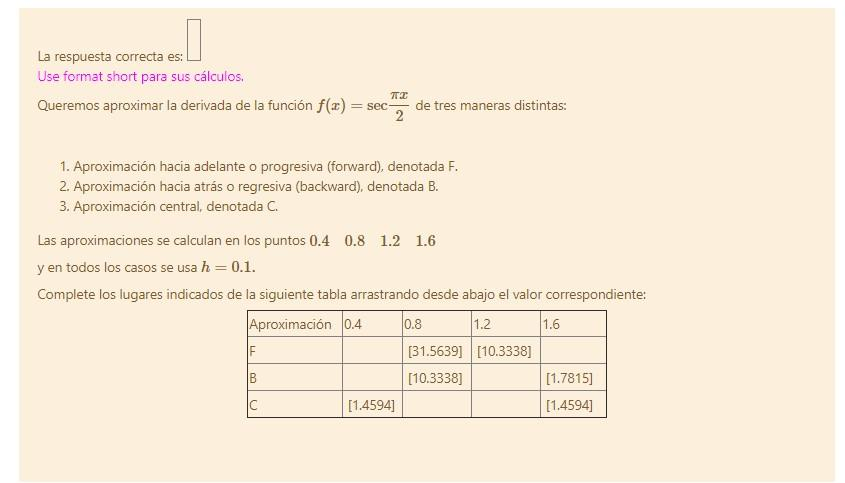

f = @(x) (2*x)./(1+x.^2);
h= 0.1; a= 0.2; b= 1.8;

c= 0.2;

% Aproximacion Progesiva
P = (f(c+h)-f(c))/h

P = 1.6584


% Aproximacion regresiva
R = (f(a)-f(a-h))/h % Valio madres, no c xq esta mala SU MADRE!!!

R = 1.8660


% Aproximacion centrada

Cn = (f(c+h)-f(c-h))/(2*h)

Cn = 1.7622


% Sda derivada

Segunda = (f(a+h)-2*f(a)+f(a-h))/(h^2)

Segunda = -2.0752